# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 5

## 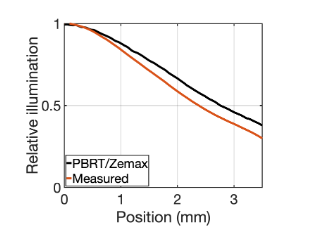

Fig. 5. Comparison of simulated and measured relative illumination. The curves show the relative illumination from the center of the sensor to a 3.5 mm field height (the sensor diagonal is 7 mm). The Zemax black box model relative illumination and ray-transfer prediction in PBRT are nearly identical (black). Neither closely matches the measured relative illumination (red), which falls-off more rapidly.

### Lens vignetting estimation

To run this code, you must have your Docker method installed and ISETCam initialized.

Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

### Load the data measured with an integrating sphere

tmp = load('p4aLensVignet_dc_inf_pos1.mat');
isphereData = tmp.pixel4aLensVignetSlope;

% Path to the relative illumination data from Zemax
RIpath = fullfile(cboxRootPath, 'data', 'lens','zemax');

% Read the Zemax data.
RIName = fullfile(RIpath, 'RI_data.txt');
RI = readmatrix(RIName);
lensVignetZemax = RI(:,1:2);

### Render a synthetic scene to estimate the relative illumination

#### Create a synthetic scene with just a flat surface

thisR = piRecipeDefault('scene name', 'flat surface');

Read 1 materials.
Read 1 textures.
***Scene parsed.


thisR.set('lights', 'delete', 'all');
infLight = piLightCreate('inflight', 'type', 'infinite');
thisR.set('light', 'add', infLight);

#### Set rendering parameters

For relatively illumination, we can use a relatively noisy rendering to see the mean

thisR.set('film resolution',[4032 3024]/16);
nRaysPerPixel = 256;
thisR.set('rays per pixel',nRaysPerPixel);
thisR.set('nbounces', 1);
thisR.set('fov', 83);
thisR.set('film diagonal', 7.056); % mm

% Add the lens to the rendering camera
lensFile = fullfile(cboxRootPath, 'data', 'lens', 'pixel4a-rearcamera-ellipse-raytransfer.json');
cameraRTF = piCameraCreate('raytransfer','lensfile',lensFile);

camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


thisR.camera = cameraRTF;

% Set the film distance so we are focused at Inf
filmDist = 0.464135918 + 0.001; % in meters
thisR.set('film distance', filmDist/1000);
piWrite(thisR);

Overwriting PBRT file /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt


### Render the image into an OI

[oiFlatSurface, result] = piRender(thisR, 'render type', 'radiance', 'scale illuminance', false,...
                    'docker image','vistalab/pbrt-v3-spectral:raytransfer-ellipse');

Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" --volume="/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface":"/Users/wandell/Documents/MATLAB/iset3d/local/flatSurface" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/renderings/flatSurface.dat /Users/wandell/Documents/MATLAB/iset3d/local/flatSurface/flatSurface.pbrt


oiName = sprintf(['CBRTF_flatsurf_filmdist_' num2str(filmDist) 'mm']);
oiFlatSurface = oiSet(oiFlatSurface, 'name', oiName);
oiFlatSurface = oiSet(oiFlatSurface, 'optics offaxismethod',  'skip');

### Calculate before and after correction

The cbSensorCreate makes the pixel4a sensor model.  We simulate the optical image impact on the sensor this way.  We use the full field, rather than just a horizontal line, because the graph shows the relative illumination along the diagonal.

sensorRTF = cbSensorCreate;

% Don't add any sensor noise
sensorRTF = sensorSet(sensorRTF, 'noise flag', -1);

% In some cases we use the measured map to correct the sensor data.
% But we do not want that in this case.
sensorRTF = cbSensorCompute(sensorRTF, oiFlatSurface,...
                            'vignettcorrection', false);

% Here is the results
voltsRTF = sensorGet(sensorRTF, 'volts');

% Caclulate the normalized relative illumination based on the green
% pixels
[lensVignetNorm, ~] = cbVignettingFitting(voltsRTF(1:2:end, 1:2:end), 'type', 'sensor');
lensVignetFullRTF = imresize(lensVignetNorm, size(isphereData));

sensorRTFCorr = cbSensorCompute(sensorRTF, oiFlatSurface,...
                            'vignettcorrection', true);

% Get the sensor voltages.
voltsRTFCorr = sensorGet(sensorRTFCorr, 'volts');

### Compare the predicted and measured curves

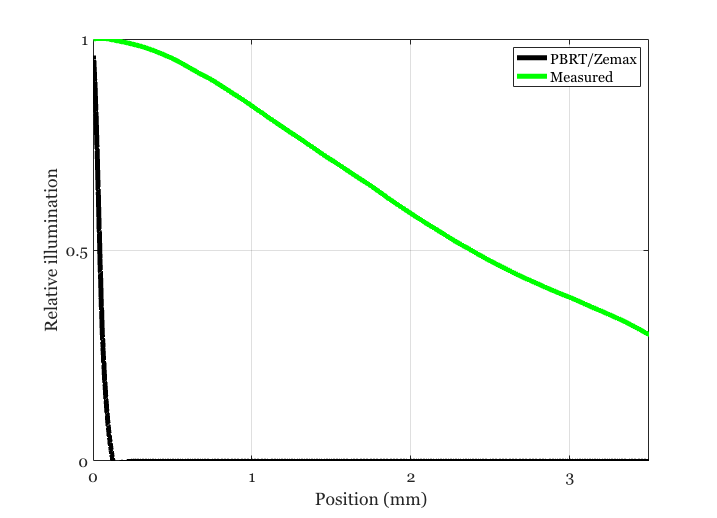

[lensVignetNorm, lensVignet] = cbVignettingFitting(voltsRTFCorr(1:2:end, 2:2:end), 'type', 'sensor');
lensVignetFullRTFCorr = imresize(lensVignetNorm, size(isphereData));

%  We pull out the diagonal intensities here.
sz = size(lensVignetFullRTFCorr);
indexX = uint16(1:sz(2)/2);
indexY = uint16(0.75 * indexX);
filmHeight = (single(indexX).^2+single(indexY).^2).^0.5*1.4/1000;
ind = sub2ind(sz, indexY+sz(1)/2-1, indexX+sz(2)/2-1);

% Zemax & RTF
% plot(lensVignetZemax(:,1), lensVignetZemax(:,2), 'LineWidth', 8);
ieNewGraphWin; hold all;
plot(filmHeight, lensVignetFullRTF(ind), 'k-', 'LineWidth', 5);
plot(filmHeight, isphereData(ind), 'LineWidth', 5)

legend('PBRT/Zemax', 'Measured');
grid on; box on; ylim([0 1]); xlim([0 3.5]); xticks(0:1:3);yticks(0:0.5:1);
xlabel('Position (mm)'); ylabel('Relative illumination');